# Surfaces defined implicitly by functions

A surface in three dimensions can also be implicitly defined by a function of three variables, $f(x,y,z)=0$. For example, the set of points (x,y,z) that satisfy the following equation


$$x^2 + y^2 + z^2 - 1 = 0$$


defines a sphere of radius 1, centered at the origin. A surface defined implicitly can be visualized using **isosurface** in Matlab. First, we will define a mesh in 3D 

x = linspace(-2,2,50);
y = linspace(-2,2,50);
z = linspace(-2,2,50);
[X,Y,Z] = meshgrid(x,y,z)

X = X(:,:,1) =

   -2.0000   -1.9184   -1.8367   -1.7551   -1.6735   -1.5918   -1.5102   -1.4286   -1.3469   -1.2653   -1.1837   -1.1020   -1.0204   -0.9388   -0.8571   -0.7755   -0.6939   -0.6122   -0.5306   -0.4490   -0.3673   -0.2857   -0.2041   -0.1224   -0.0408    0.0408    0.1224    0.2041    0.2857    0.3673    0.4490    0.5306    0.6122    0.6939    0.7755    0.8571    0.9388    1.0204    1.1020    1.1837    1.2653    1.3469    1.4286    1.5102    1.5918    1.6735    1.7551    1.8367    1.9184    2.0000
   -2.0000   -1.9184   -1.8367   -1.7551   -1.6735   -1.5918   -1.5102   -1.4286   -1.3469   -1.2653   -1.1837   -1.1020   -1.0204   -0.9388   -0.8571   -0.7755   -0.6939   -0.6122   -0.5306   -0.4490   -0.3673   -0.2857   -0.2041   -0.1224   -0.0408    0.0408    0.1224    0.2041    0.2857    0.3673    0.4490    0.5306    0.6122    0.6939    0.7755    0.8571    0.9388    1.0204    1.1020    1.1837    1.2653    1.3469    1.4286    1.5102    1.5918    1.6735    1.7551    1.8367   

Y = Y(:,:,1) =

   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000
   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   

Z = Z(:,:,1) =

    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2   

Notice that the call to **meshgrid** returns three matrices, X, Y, and Z, all of which contain 50 x 50 x 50 points. These are the x coordinates, y coordinates, and z coordinates respectively at each point on the mesh. 

We now define a function that computes the value of the function at any mesh point. You will find this function at the end of this script, and we copy it here for clarity

**function res = sphere(x,y,z)**

**    res = x.^2 + y.^2 + z.^2 - 1**

**end**

Notice that we use the **.^** operator since the input arguments to this function can and will be matrices. Now we can call this function and visualize the surface

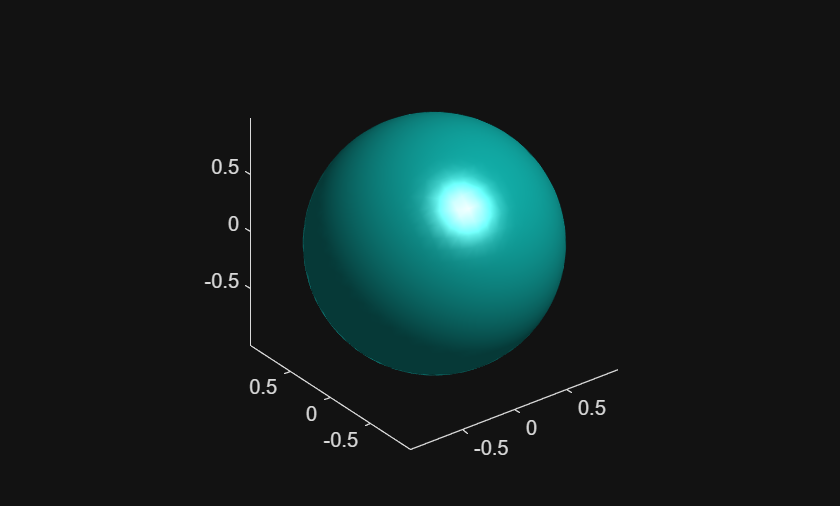

V = sphere(X,Y,Z);
isosurface(X,Y,Z,V,0)
axis('equal')

## Generalization

There are lots of implicit surfaces, but a particularly important group is the quadratic (or quadric) surfaces, defined by the equation


$$A x^2 + By^2 + C z^2 + Dyz+Ezx+Fxy+Gx+Hy+Iz+J = 0$$


where A, B, C, D, E, F, G, H, I, and J are all arbitrary constants, some of which may be zero.

**Exercise 1: **Consider the surface defined by the equation $\frac{x^2}{a^2} + \frac{y^2}{b^2} + \frac{z^2}{c^2}-1=0$

- Write a function that accepts x, y, z, a, b, and c as input and returns the value of the expression on the left hand side.

- Visualize the surface for some different values of a, b, and c.

- What features of the surface do a, b, and c control?

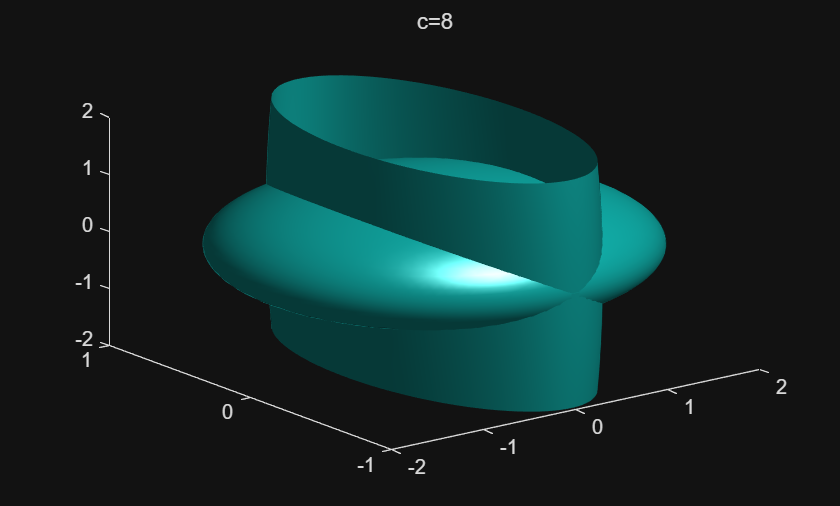

V = gen(X,Y,Z,2,1,1);
isosurface(X,Y,Z,V,0);

V = V(:,:,1) =

    8.0000    7.9200    7.8434    7.7701    7.7001    7.6335    7.5702    7.5102    7.4536    7.4002    7.3503    7.3036    7.2603    7.2203    7.1837    7.1504    7.1204    7.0937    7.0704    7.0504    7.0337    7.0204    7.0104    7.0037    7.0004    7.0004    7.0037    7.0104    7.0204    7.0337    7.0504    7.0704    7.0937    7.1204    7.1504    7.1837    7.2203    7.2603    7.3036    7.3503    7.4002    7.4536    7.5102    7.5702    7.6335    7.7001    7.7701    7.8434    7.9200    8.0000
    7.6801    7.6002    7.5235    7.4502    7.3803    7.3136    7.2503    7.1903    7.1337    7.0804    7.0304    6.9838    6.9404    6.9005    6.8638    6.8305    6.8005    6.7738    6.7505    6.7305    6.7139    6.7005    6.6905    6.6839    6.6805    6.6805    6.6839    6.6905    6.7005    6.7139    6.7305    6.7505    6.7738    6.8005    6.8305    6.8638    6.9005    6.9404    6.9838    7.0304    7.0804    7.1337    7.1903    7.2503    7.3136    7.3803    7.4502    7.5235   

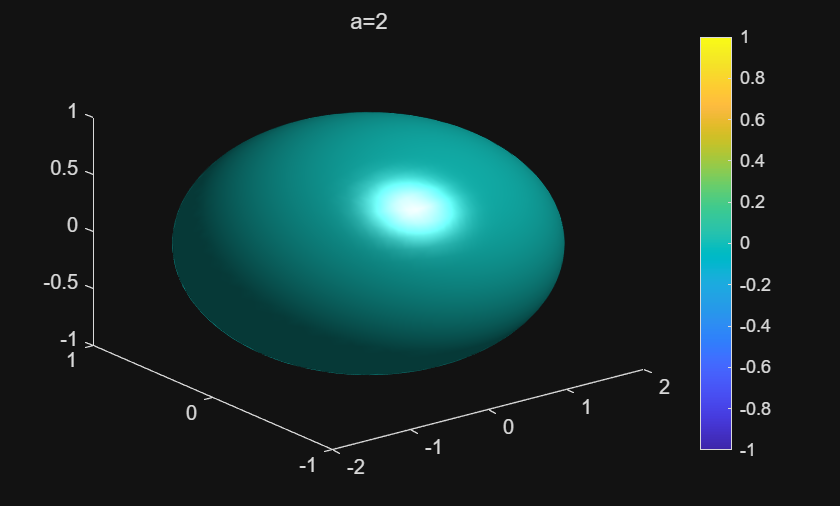

V = V(:,:,1) =

    7.2500    7.2300    7.2108    7.1925    7.1750    7.1584    7.1425    7.1276    7.1134    7.1001    7.0876    7.0759    7.0651    7.0551    7.0459    7.0376    7.0301    7.0234    7.0176    7.0126    7.0084    7.0051    7.0026    7.0009    7.0001    7.0001    7.0009    7.0026    7.0051    7.0084    7.0126    7.0176    7.0234    7.0301    7.0376    7.0459    7.0551    7.0651    7.0759    7.0876    7.1001    7.1134    7.1276    7.1425    7.1584    7.1750    7.1925    7.2108    7.2300    7.2500
    6.9301    6.9101    6.8910    6.8727    6.8552    6.8385    6.8227    6.8077    6.7935    6.7802    6.7677    6.7560    6.7452    6.7352    6.7261    6.7177    6.7102    6.7036    6.6977    6.6927    6.6886    6.6852    6.6827    6.6811    6.6802    6.6802    6.6811    6.6827    6.6852    6.6886    6.6927    6.6977    6.7036    6.7102    6.7177    6.7261    6.7352    6.7452    6.7560    6.7677    6.7802    6.7935    6.8077    6.8227    6.8385    6.8552    6.8727    6.8910   

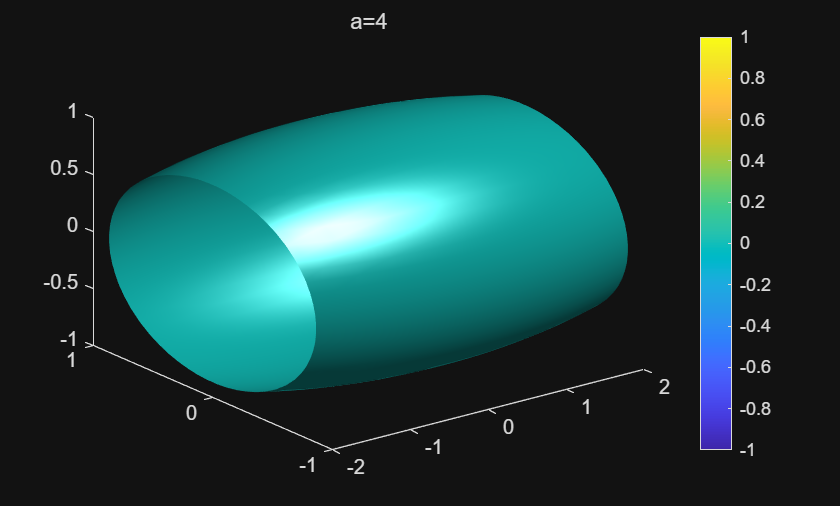

V = V(:,:,1) =

    7.0625    7.0575    7.0527    7.0481    7.0438    7.0396    7.0356    7.0319    7.0283    7.0250    7.0219    7.0190    7.0163    7.0138    7.0115    7.0094    7.0075    7.0059    7.0044    7.0031    7.0021    7.0013    7.0007    7.0002    7.0000    7.0000    7.0002    7.0007    7.0013    7.0021    7.0031    7.0044    7.0059    7.0075    7.0094    7.0115    7.0138    7.0163    7.0190    7.0219    7.0250    7.0283    7.0319    7.0356    7.0396    7.0438    7.0481    7.0527    7.0575    7.0625
    6.7426    6.7376    6.7328    6.7283    6.7239    6.7197    6.7158    6.7120    6.7085    6.7051    6.7020    6.6991    6.6964    6.6939    6.6916    6.6895    6.6877    6.6860    6.6845    6.6833    6.6822    6.6814    6.6808    6.6804    6.6802    6.6802    6.6804    6.6808    6.6814    6.6822    6.6833    6.6845    6.6860    6.6877    6.6895    6.6916    6.6939    6.6964    6.6991    6.7020    6.7051    6.7085    6.7120    6.7158    6.7197    6.7239    6.7283    6.7328   

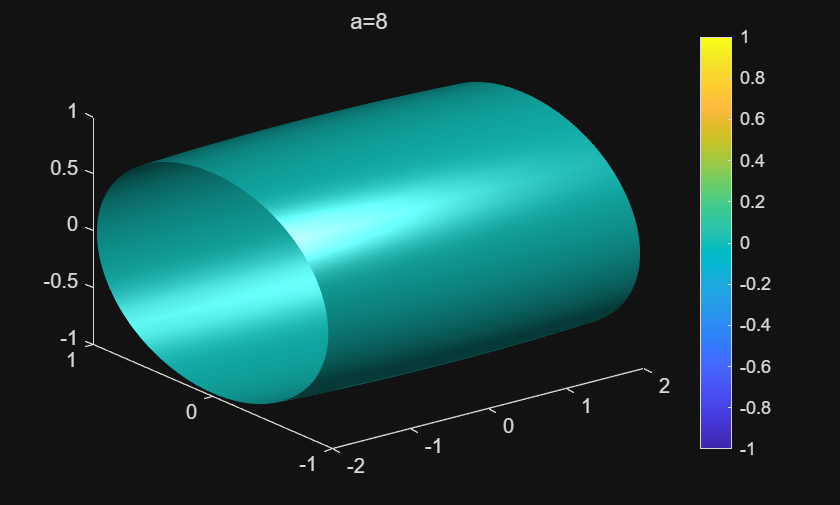

alpha = [2 4 8];
beta = alpha;
cigma = alpha;
%b,c control,do a
for a = alpha
    figure;
    V = gen(X,Y,Z,a,1,1)
    isosurface(X,Y,Z,V,0)
    title('a='+string(a))
    shading flat;
    colorbar
end

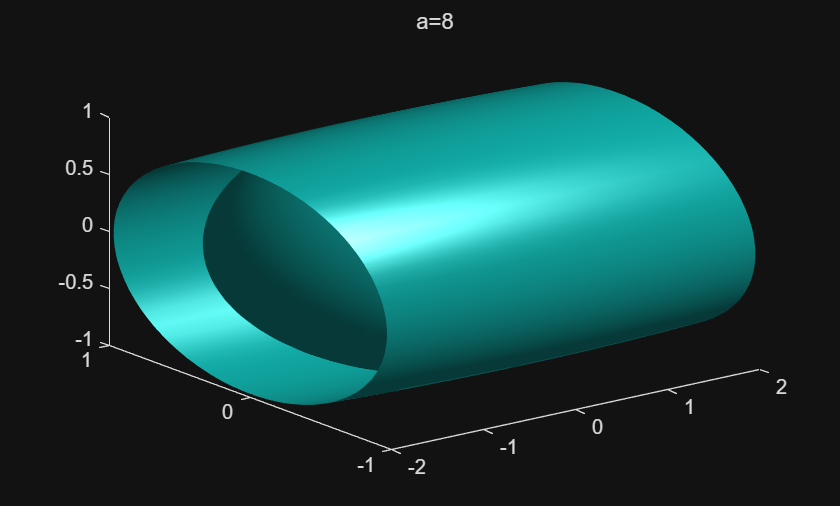

V = gen(X,Y,Z,2,1,1);
isosurface(X,Y,Z,V,0);

V = V(:,:,1) =

    8.0000    7.6801    7.3736    7.0804    6.8005    6.5339    6.2807    6.0408    5.8142    5.6010    5.4011    5.2145    5.0412    4.8813    4.7347    4.6014    4.4815    4.3748    4.2815    4.2016    4.1349    4.0816    4.0416    4.0150    4.0017    4.0017    4.0150    4.0416    4.0816    4.1349    4.2016    4.2815    4.3748    4.4815    4.6014    4.7347    4.8813    5.0412    5.2145    5.4011    5.6010    5.8142    6.0408    6.2807    6.5339    6.8005    7.0804    7.3736    7.6801    8.0000
    7.9200    7.6002    7.2936    7.0004    6.7205    6.4540    6.2007    5.9608    5.7343    5.5210    5.3211    5.1345    4.9613    4.8013    4.6547    4.5214    4.4015    4.2949    4.2016    4.1216    4.0550    4.0017    3.9617    3.9350    3.9217    3.9217    3.9350    3.9617    4.0017    4.0550    4.1216    4.2016    4.2949    4.4015    4.5214    4.6547    4.8013    4.9613    5.1345    5.3211    5.5210    5.7343    5.9608    6.2007    6.4540    6.7205    7.0004    7.2936   

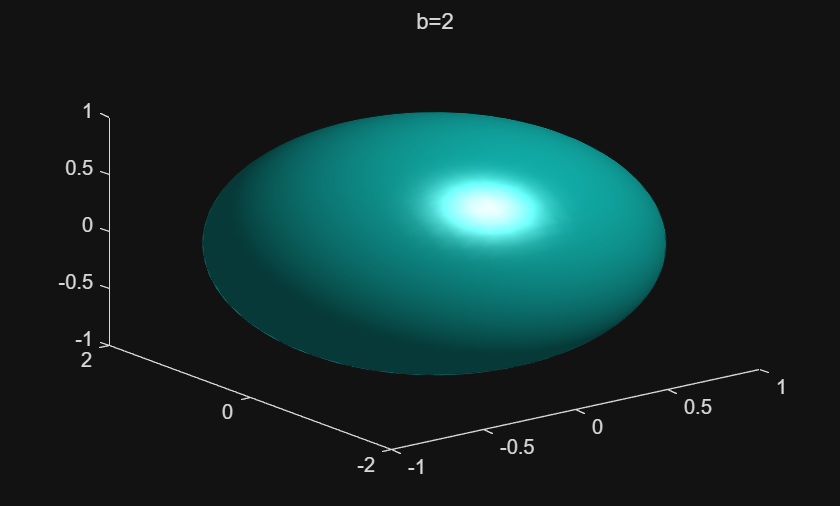

V = V(:,:,1) =

    7.2500    6.9301    6.6236    6.3304    6.0505    5.7839    5.5307    5.2908    5.0642    4.8510    4.6511    4.4645    4.2912    4.1313    3.9847    3.8514    3.7315    3.6248    3.5315    3.4516    3.3849    3.3316    3.2916    3.2650    3.2517    3.2517    3.2650    3.2916    3.3316    3.3849    3.4516    3.5315    3.6248    3.7315    3.8514    3.9847    4.1313    4.2912    4.4645    4.6511    4.8510    5.0642    5.2908    5.5307    5.7839    6.0505    6.3304    6.6236    6.9301    7.2500
    7.2300    6.9101    6.6036    6.3104    6.0305    5.7640    5.5107    5.2708    5.0443    4.8310    4.6311    4.4445    4.2712    4.1113    3.9647    3.8314    3.7115    3.6049    3.5116    3.4316    3.3650    3.3116    3.2717    3.2450    3.2317    3.2317    3.2450    3.2717    3.3116    3.3650    3.4316    3.5116    3.6049    3.7115    3.8314    3.9647    4.1113    4.2712    4.4445    4.6311    4.8310    5.0443    5.2708    5.5107    5.7640    6.0305    6.3104    6.6036   

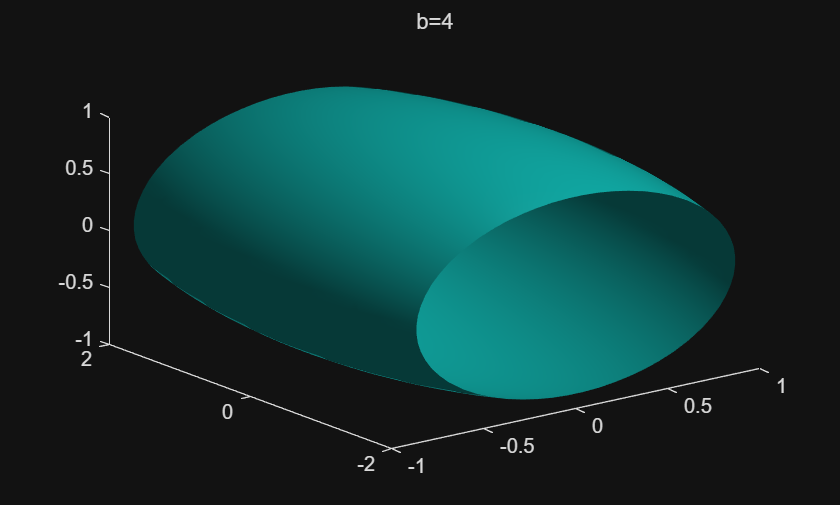

V = V(:,:,1) =

    7.0625    6.7426    6.4361    6.1429    5.8630    5.5964    5.3432    5.1033    4.8767    4.6635    4.4636    4.2770    4.1037    3.9438    3.7972    3.6639    3.5440    3.4373    3.3440    3.2641    3.1974    3.1441    3.1041    3.0775    3.0642    3.0642    3.0775    3.1041    3.1441    3.1974    3.2641    3.3440    3.4373    3.5440    3.6639    3.7972    3.9438    4.1037    4.2770    4.4636    4.6635    4.8767    5.1033    5.3432    5.5964    5.8630    6.1429    6.4361    6.7426    7.0625
    7.0575    6.7376    6.4311    6.1379    5.8580    5.5914    5.3382    5.0983    4.8717    4.6585    4.4586    4.2720    4.0987    3.9388    3.7922    3.6589    3.5390    3.4323    3.3391    3.2591    3.1924    3.1391    3.0992    3.0725    3.0592    3.0592    3.0725    3.0992    3.1391    3.1924    3.2591    3.3391    3.4323    3.5390    3.6589    3.7922    3.9388    4.0987    4.2720    4.4586    4.6585    4.8717    5.0983    5.3382    5.5914    5.8580    6.1379    6.4311   

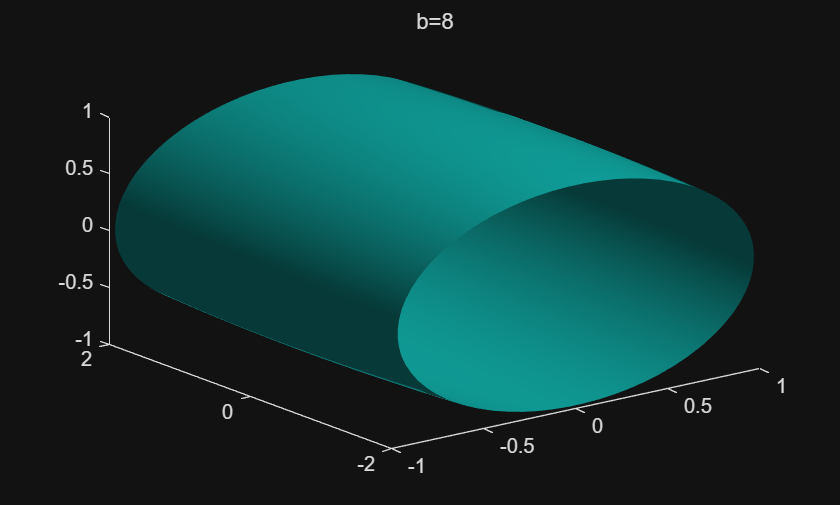

alpha = [2 4 8];
beta = alpha;
cigma = alpha;
%a,c control,do b
for b = beta
    figure;
    V = gen(X,Y,Z,1,b,1)
    isosurface(X,Y,Z,V,0)
    title('b='+string(b))
end

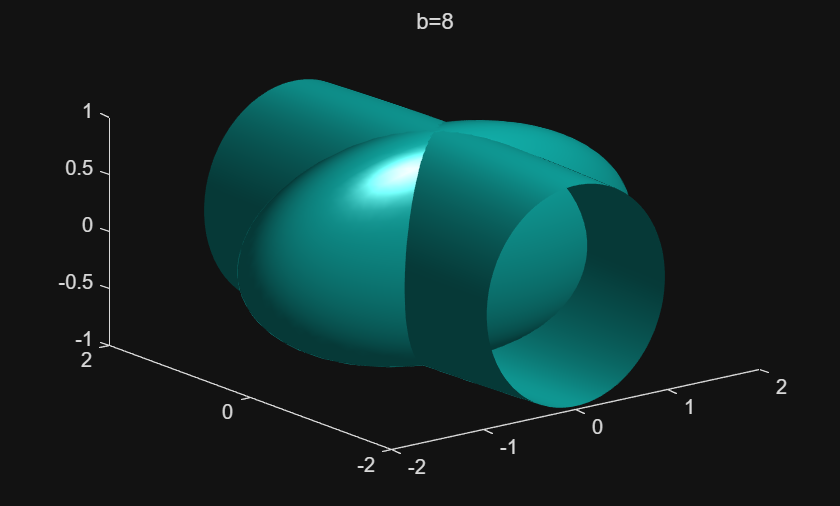

V = gen(X,Y,Z,2,1,1);
isosurface(X,Y,Z,V,0);

V = V(:,:,1) =

    8.0000    7.6801    7.3736    7.0804    6.8005    6.5339    6.2807    6.0408    5.8142    5.6010    5.4011    5.2145    5.0412    4.8813    4.7347    4.6014    4.4815    4.3748    4.2815    4.2016    4.1349    4.0816    4.0416    4.0150    4.0017    4.0017    4.0150    4.0416    4.0816    4.1349    4.2016    4.2815    4.3748    4.4815    4.6014    4.7347    4.8813    5.0412    5.2145    5.4011    5.6010    5.8142    6.0408    6.2807    6.5339    6.8005    7.0804    7.3736    7.6801    8.0000
    7.6801    7.3603    7.0537    6.7605    6.4806    6.2141    5.9608    5.7209    5.4944    5.2811    5.0812    4.8946    4.7214    4.5614    4.4148    4.2815    4.1616    4.0550    3.9617    3.8817    3.8151    3.7618    3.7218    3.6951    3.6818    3.6818    3.6951    3.7218    3.7618    3.8151    3.8817    3.9617    4.0550    4.1616    4.2815    4.4148    4.5614    4.7214    4.8946    5.0812    5.2811    5.4944    5.7209    5.9608    6.2141    6.4806    6.7605    7.0537   

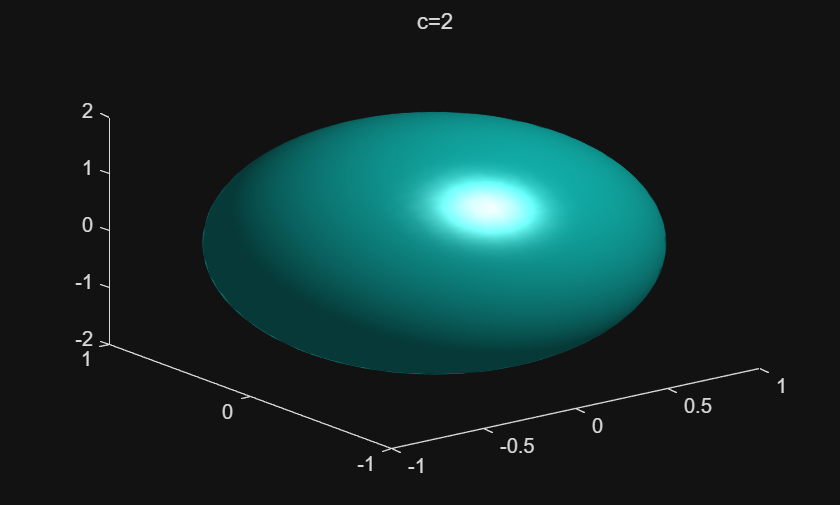

V = V(:,:,1) =

    7.2500    6.9301    6.6236    6.3304    6.0505    5.7839    5.5307    5.2908    5.0642    4.8510    4.6511    4.4645    4.2912    4.1313    3.9847    3.8514    3.7315    3.6248    3.5315    3.4516    3.3849    3.3316    3.2916    3.2650    3.2517    3.2517    3.2650    3.2916    3.3316    3.3849    3.4516    3.5315    3.6248    3.7315    3.8514    3.9847    4.1313    4.2912    4.4645    4.6511    4.8510    5.0642    5.2908    5.5307    5.7839    6.0505    6.3304    6.6236    6.9301    7.2500
    6.9301    6.6103    6.3037    6.0105    5.7306    5.4641    5.2108    4.9709    4.7444    4.5311    4.3312    4.1446    3.9714    3.8114    3.6648    3.5315    3.4116    3.3050    3.2117    3.1317    3.0651    3.0118    2.9718    2.9451    2.9318    2.9318    2.9451    2.9718    3.0118    3.0651    3.1317    3.2117    3.3050    3.4116    3.5315    3.6648    3.8114    3.9714    4.1446    4.3312    4.5311    4.7444    4.9709    5.2108    5.4641    5.7306    6.0105    6.3037   

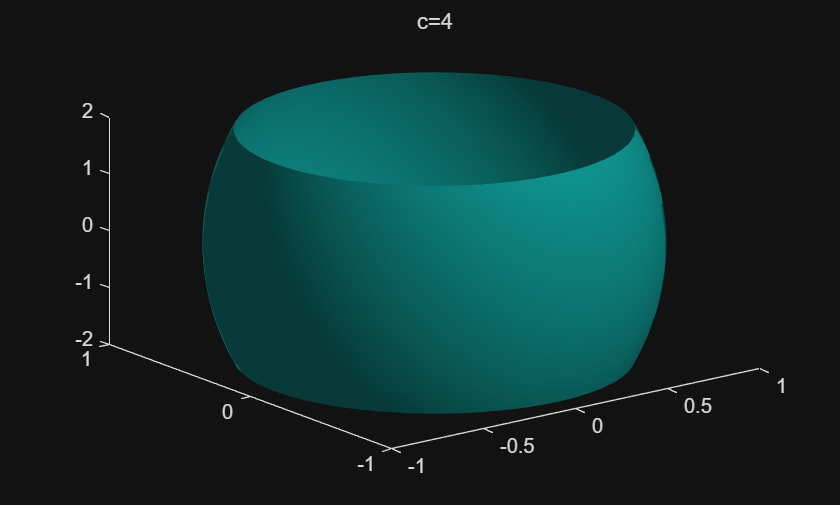

V = V(:,:,1) =

    7.0625    6.7426    6.4361    6.1429    5.8630    5.5964    5.3432    5.1033    4.8767    4.6635    4.4636    4.2770    4.1037    3.9438    3.7972    3.6639    3.5440    3.4373    3.3440    3.2641    3.1974    3.1441    3.1041    3.0775    3.0642    3.0642    3.0775    3.1041    3.1441    3.1974    3.2641    3.3440    3.4373    3.5440    3.6639    3.7972    3.9438    4.1037    4.2770    4.4636    4.6635    4.8767    5.1033    5.3432    5.5964    5.8630    6.1429    6.4361    6.7426    7.0625
    6.7426    6.4228    6.1162    5.8230    5.5431    5.2766    5.0233    4.7834    4.5569    4.3436    4.1437    3.9571    3.7839    3.6239    3.4773    3.3440    3.2241    3.1175    3.0242    2.9442    2.8776    2.8243    2.7843    2.7576    2.7443    2.7443    2.7576    2.7843    2.8243    2.8776    2.9442    3.0242    3.1175    3.2241    3.3440    3.4773    3.6239    3.7839    3.9571    4.1437    4.3436    4.5569    4.7834    5.0233    5.2766    5.5431    5.8230    6.1162   

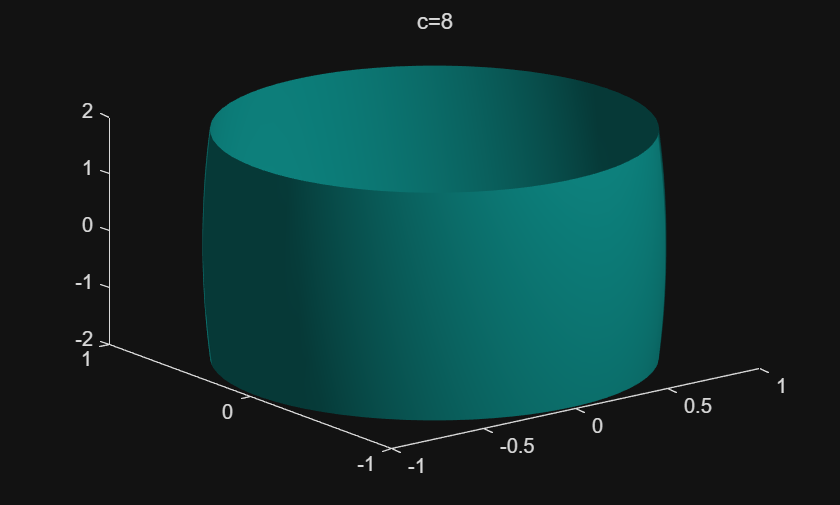

alpha = [2 4 8];
beta = alpha;
cigma = alpha;
%a,b control,do c
for c = cigma
    figure;
    V = gen(X,Y,Z,1,1,c)
    isosurface(X,Y,Z,V,0)
    title('c='+string(c))
end

function res = gen(x,y,z,a,b,c)

res = x.^2/a^2+y.^2/b^2 + z.^2/c^2 - 1;

end


## Function definitions

function res = sphere(x,y,z)
    res = x.^2 + y.^2 + z.^2 - 1;
end
